clc
clear all
close all
load("band.mat");

% Import data from text file
data = readtable("C:\Users\manub\OneDrive - University of Twente\Documents\documenten\School\University\Module 9\4. Project\Spooner-UTwente\MATLAB-filterDesigner\\mes2.csv");

% Display results
data

data = 700×4 table
    Time_s    Channel_0    Channel_1    Channel_2
    ______    _________    _________    _________

    8.0233     0.47253      0.34237      0.23345 
    8.0267     0.46374      0.30793      0.22466 
      8.03     0.46007      0.32772      0.22759 
    8.0333     0.45495      0.33455      0.22881 
    8.0367     0.44811      0.46154      0.26374 
      8.04      0.4508      0.67179      0.33211 
    8.0433     0.45837      0.74676      0.38364 
    8.0467     0.46203      0.75361      0.41489 
      8.05     0.47228      0.65544       0.4127 
    8.0533     0.48058      0.49303      0.37754 
    8.0567     0.47399      0.33651       0.3243 
      8.06     0.46178      0.29401      0.28766 
    8.0633     0.45202        0.337      0.27668 
    8.0667     0.45397      0.39097      0.27692 
      8.07     0.45544      0.52503       0.

data.Time_s = data.Time_s - data.Time_s(1);

# FFT

T = data.Time_s(2);
Fs = 1/T;
L = size(data.Time_s,1);
t = (0:L-1)*T;

X = data.Channel_0;

X =     0.4725
    0.4637
    0.4601
    0.4549
    0.4481
    0.4508
    0.4584
    0.4620
    0.4723
    0.4806


Plot the signal in the time domain.

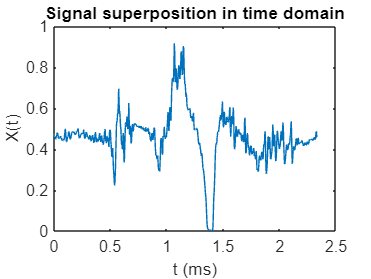

plot(t,X)
title("Signal superposition in time domain")
xlabel("t (ms)")
ylabel("X(t)")

Compute the Fourier transform of the signal.

Y = fft(X);

Compute the single-sided amplitude spectrum of the signal.

f = Fs*(0:(L-1)/2)/L;
P2 = abs(Y/L);
P1 = P2(1:(L+1)/2);

P1(2:end) = 2*P1(2:end);

In the frequency domain, plot the single-sided spectrum. Because the time sampling of the signal is quite short, the frequency resolution of the Fourier transform is not precise enough to show the peak frequency near 4 Hz.

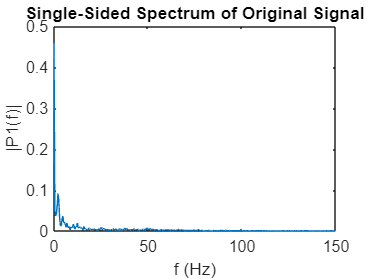

plot(f,P1) 
title("Single-Sided Spectrum of Original Signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

To better assess the peak frequencies, you can increase the length of the analysis window by padding the original signal with zeros. This method automatically interpolates the Fourier transform of the signal with a more precise frequency resolution.

Identify a new input length that is the next power of 2 from the original signal length. Pad the signal `X` with trailing zeros to extend its length. Compute the Fourier transform of the zero-padded signal.

n = 2^nextpow2(L);
Y = fft(X,n);

Compute the single-sided amplitude spectrum of the padded signal. Because the signal length `n` increased from 65 to 128, the frequency resolution becomes  `Fs/n`, which is 0.625 Hz.

f = Fs*(0:(n/2))/n;
P2 = abs(Y/L);
P1 = P2(1:n/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Plot the single-sided spectrum of the padded signal. This new spectrum shows the peak frequencies near 2 Hz, 4 Hz, and 6 Hz within the frequency resolution of 0.625 Hz.

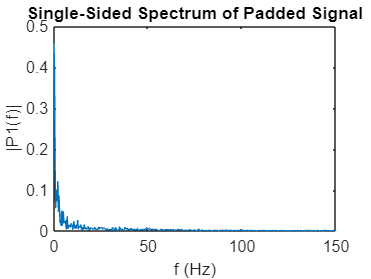

plot(f,P1) 
title("Single-Sided Spectrum of Padded Signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

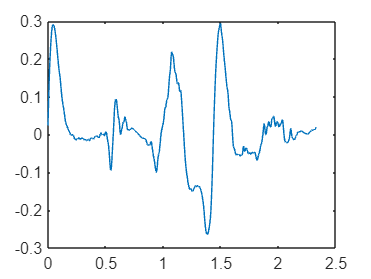


filtered = filter(Hd, X);
plot(t,filtered);

*Copyright 2022 The MathWorks, Inc.*